clc; clear variables; clf;

# Avance 2: Entrenamiento, adecuación y evaluación de modelos

Para este avance se tomarán los diferentes datasets obtenidos en el avance 1 y se procederá a buscar el mejor/mejores modelos de clasificación para predecir la posibilidad de intento de suicidio recurrente.

En un primer momento se probarán diferentes modelos, haciendo uso de la herramienta   "Classification Learner" de Matlab, debido a su facilidad y rapidez para probar múltiples modelos simultáneamente. Se tomarán los pares data set-modelo que mejores resultados den (preferiblemente por encima de 70% de acierto) para seguirlos desarrollando, en términos de selección de parámetros y optimización de hiperparámetros.

Para la selección de parámetros y ajuste de hiperparámetros, en donde sea posible se usarán herramientas las interactivas o automáticas que provee Matlab. 

Como métodos de validación y calificación de los modelos se pretenden usar los dados a continuación

- Matriz de confusión

- ROC curve

Al momento de realizar predicciones generarán resultados determinísticos, para una ocasión posterior se pretende incluir predicción probabilística

## Data sets de entrada.

En el avance 1 se obtuvieron 4 datasets después del proceso de limpieza, los cuales se mencionan a continuación:

- cds_imputed: dataset con 33 características y 4146 registros

- cds: dataset con 28 características 4146 registros, 

- cds_few: dataset 33 características y 655 registros

- cds_fem_minus_alcohol:  dataset 32 características 1690 registros.

cds = readtable('..\clean_datasets\cds.csv'); size_cds = size(cds)

size_cds =         4146          29


cds_imputed = readtable('..\clean_datasets\cds_imputed.csv'); size_imputed = size(cds_imputed)

size_imputed =         4146          34


cds_imputed = movevars(cds_imputed,'inten_prev','after','tipo_ss_S');
cds_few = readtable('..\clean_datasets\cds_few.csv'); size_few = size (cds_few)

size_few =    655    34


cds_few_minus_alcohol = readtable('..\clean_datasets\cds_few_minus_alcohol.csv');
       size_few_minus_alcohol = size (cds_few_minus_alcohol)

size_few_minus_alcohol =         1690          33


Con estos dataset se procede realizar un entrenamiento exploratorio de modelos, para continuar con los más prometedores. Sin embargo, es necesario definir el concepto de "más prometedor". En este primer momento se tendrá en cuanta la exactitud de los modelos

Es de utilidad tener en cuenta que para el entrenamiento de los modelos fue usada validación cruzada con "k-folds” (k=5), así, el valor de la exactitud presentado corresponde a la exactitud de validación y esta sirve como un estimado del desempeño del modelo en nuevos datos comparados con el conjunto de entrenamiento.

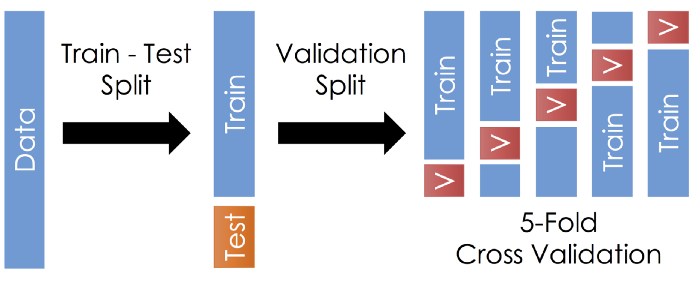

**Resultados cds**

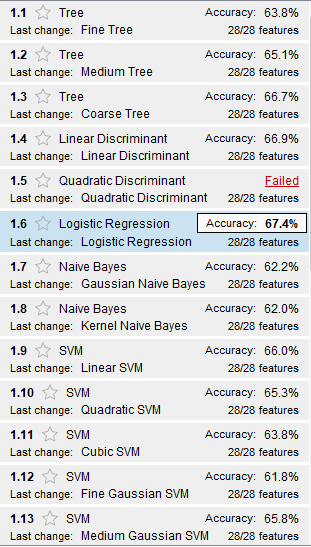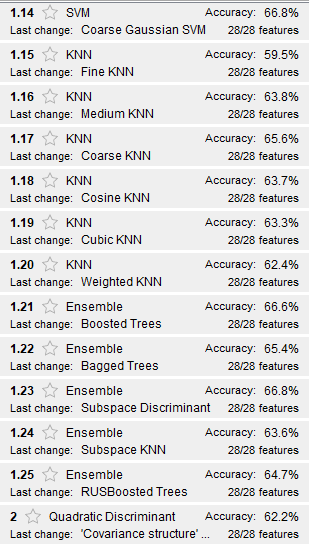

**Resultados cds_imputed**

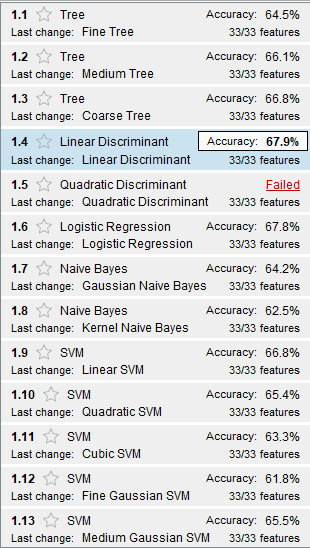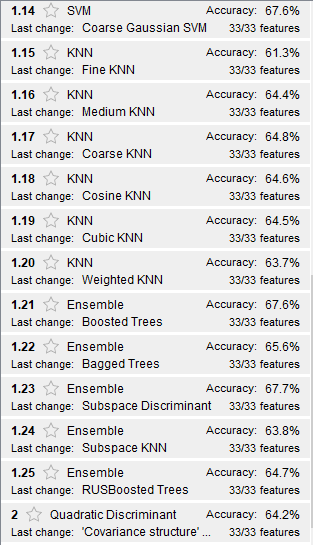

**Resultados cds_few**

Para este dataset algunos modelos se hicieron individualmente, porque presentaban problemas con las características 'antec_tran', 'tipo_ss_I', 'suici_fm_a' y 'tipo_SS_P ya que la mayoría o casi todos sus valores son iguales por lo que no aportan información o no presentan variación con respecto a una de las clases por hallar.

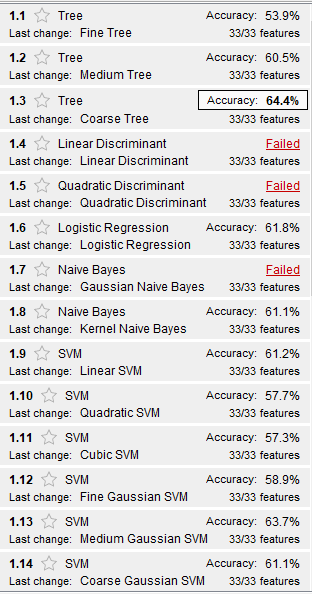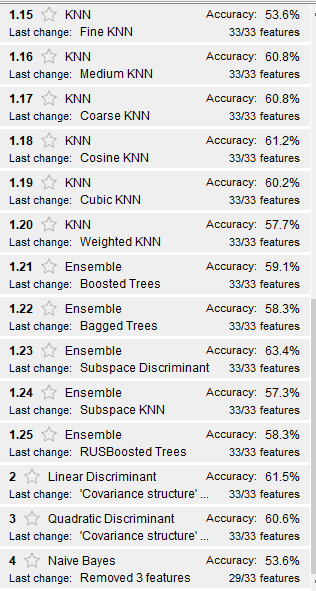

**Resultados cds_few_minus_alcohol**

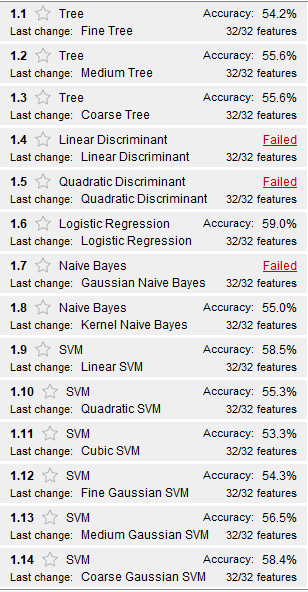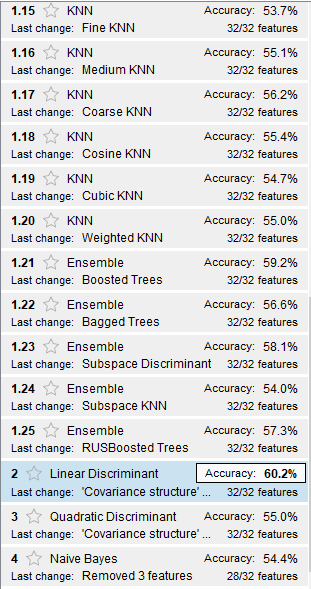

Por motivos exploratorios se realizaron pruebas aplicándole PCA a los datos, pero los resultados en general fueron inferiores a los obtenidos sin esta transformación, por lo que esta transformación de los datos no será utilizada.

Como se puede notar, ningún par dataset-modelo obtuvo una precisión mayor al 70% tal y como se había definido inicialmente para su aceptación. Por este motivo se tomará aquel dataset que produjo el modelo con la mayor precisión(cds_imputed) y los mejores modelos obtenidos a partir de este -Coarse Tree, Linear discriminant, Logistic regresion, SVM (linear y coarse) y Ensamble (BoostTrees)-

### **Feature selection**

Buscando reducir la dimensionalidad y explorar diferentes opciones se pretende realizar un proceso de selección de características. Esto se hará filtrando aquellas características menos importantes para la respuesta 'inten_prev' mediante el algoritmo MRMR (Minimum Redundancy Maximun Relevance), del cual se puede obtener el "ranking" de importancia de los predictores teniendo en cuentas la respuesta.

Se entrenarán 2 modelos, uno con todas las características y adicionalmente otro con el conjunto de las 7 más importantes

idx = fscmrmr(cds_imputed,'inten_prev');
most_signif_features = cds_imputed.Properties.VariableNames(idx(1:7)).'

most_signif_features = 7×1 cell array
    {'antec_tran'}
    {'hist_famil'}
    {'muerte_fam'}
    {'antec_v_a' }
    {'prob_consu'}
    {'plan_suici'}
    {'gp_psiquia'}


less_signif_features =cds_imputed.Properties.VariableNames(idx(end-4:end)).'

less_signif_features = 5×1 cell array
    {'escolarid' }
    {'esco_educ' }
    {'tipo_ss_C' }
    {'trab_socia'}
    {'sexo_'     }


## Optimización de hiperparámetros

Para la optimización de hiperparámetros serán utilizados dos enfoques:

Para los modelos simples (arboles de decisión) se realizará mediante GridSearch, mientras que para los más complejos (Ensamble, SVM) será utilizado un método de optimización bayesiana, el cual, a través de 30 iteraciones se va redirigiendo hacia aquellos hiperparámetros del espacio de búsqueda que proveen mejores resultados para el modelo. Esta elección se hace debido a los costos computacionales elevados de realizar Grid o Random Search en modelos complejos.

Como parte del proceso de optimización se obtiene el gráfico de error de clasificación mínimo en el cual se encuentran principalmente:

- Los resultados de la optimización

- El mínimo error de clasificación observado (puntos azules) hasta la iteración actual

- Bestpoint hyperparameters (cuadrado rojo), indica la iteración que corresponde a los valores de los hiperparámetros optimizados

Los resultados se presentarán a continuación para cada modelo:

**Arboles de decisión:**

En la anterior etapa mejores resultados fueron obtenidos con árboles de decisión gruesos (con poco número de splits), lo cual es confirmado con los resultados de este proceso

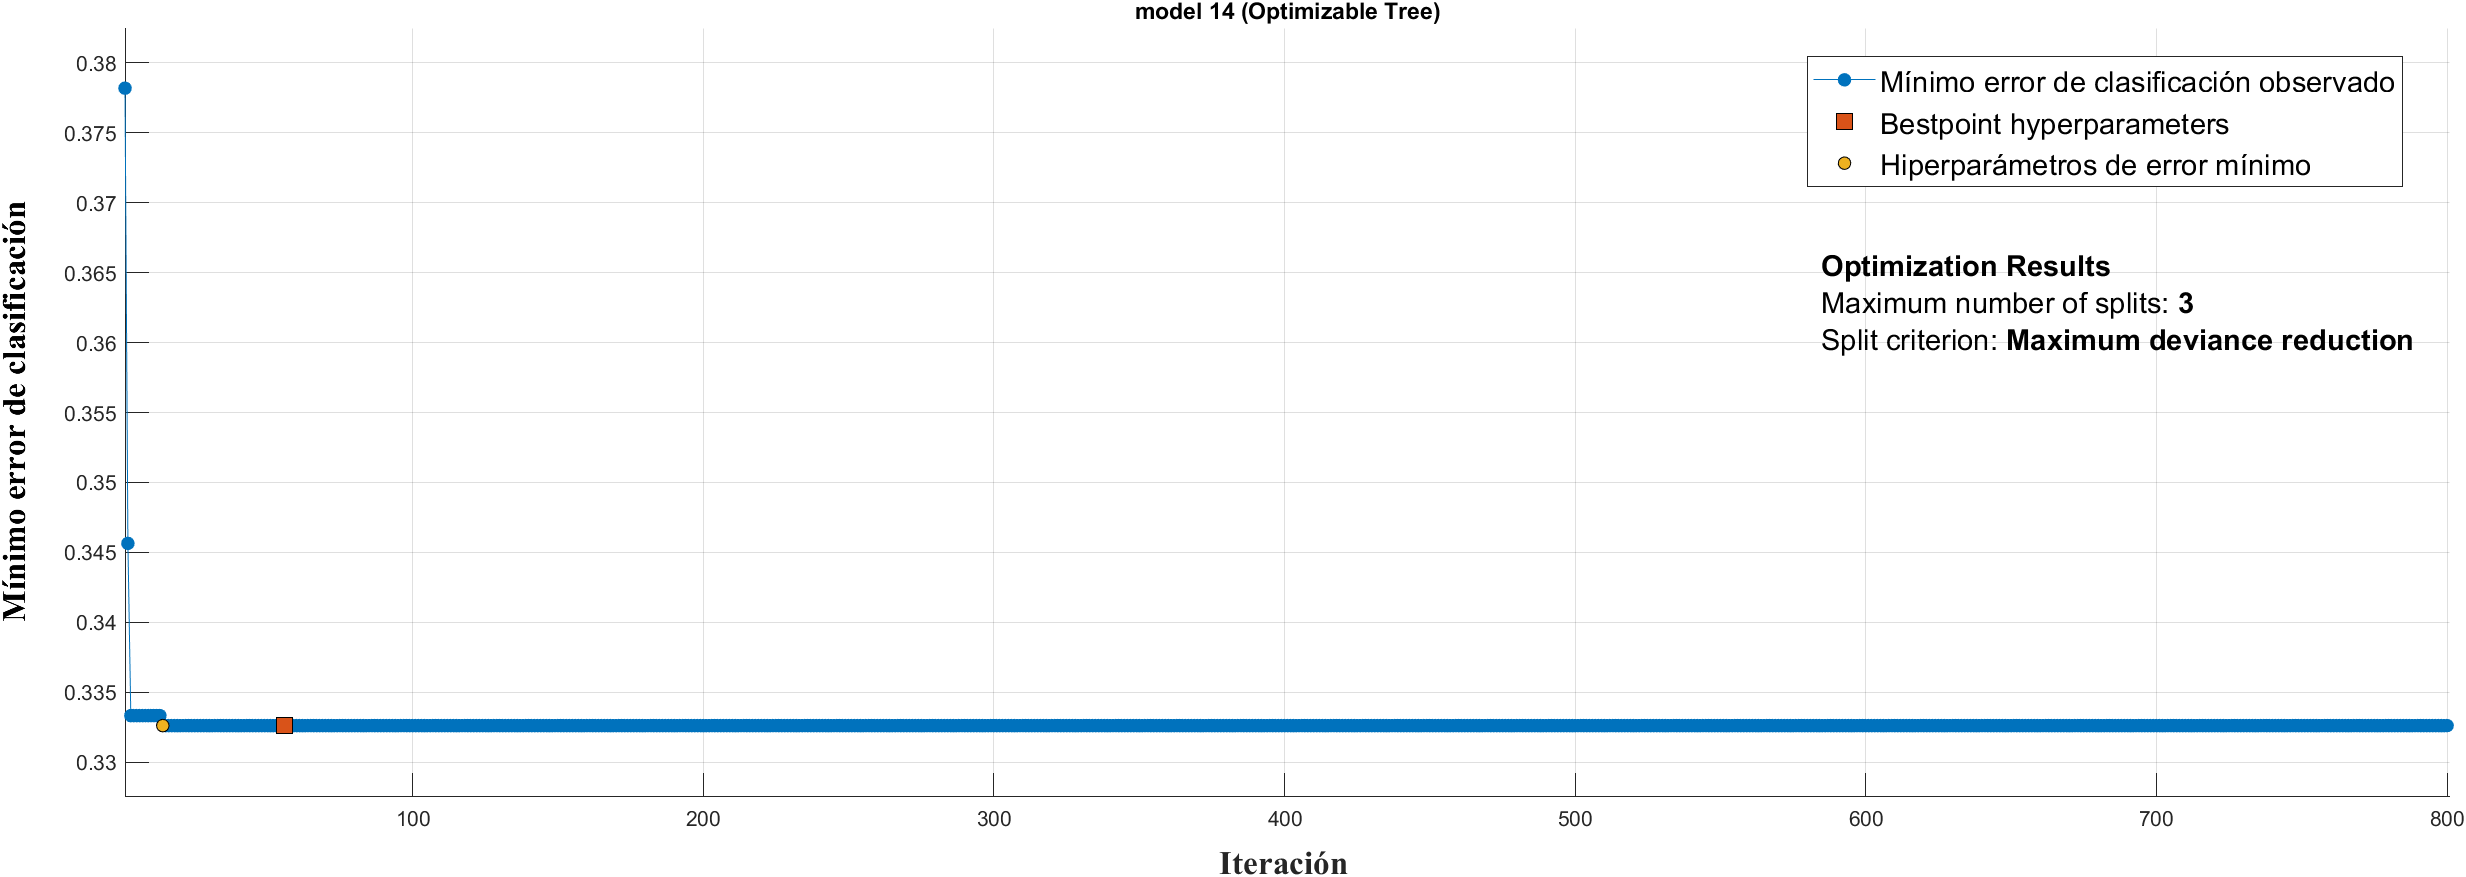

**Arboles de decisión (7 características):**

Para este caso los mejore resultados fueron con árboles finos

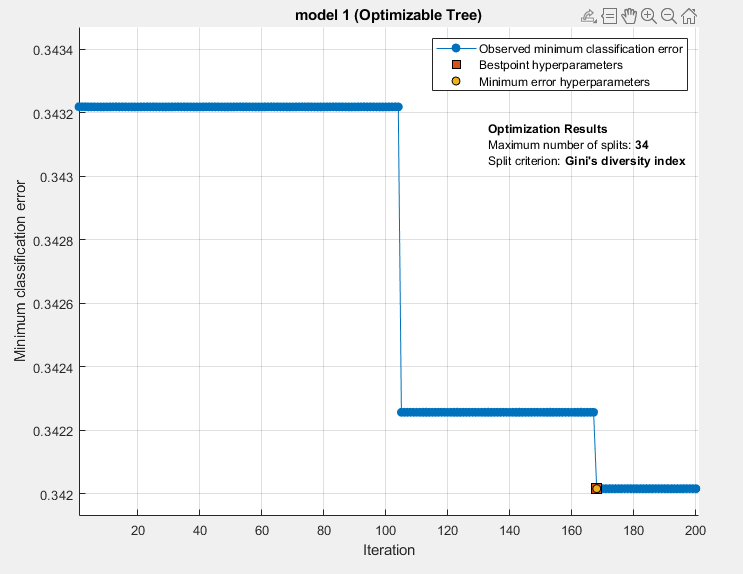

**Discriminante: **

Anteriormente se había hallado que el lineal era el que mejores resultados presentaba, esto se comprueba/reafirma al realizar este paso.

Las combinaciones disponibles para este tipo de modelos son pocas por lo que con pocas iteraciones es suficiente

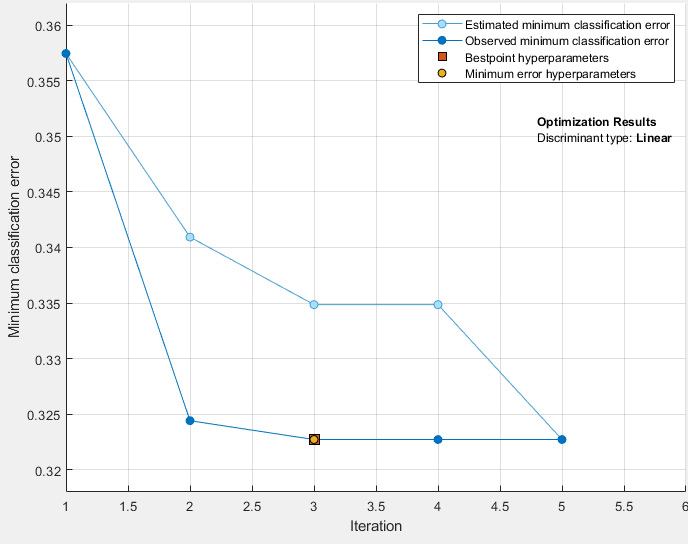

**Discriminante (7 características):**

Mejores resultados con diagonal linear

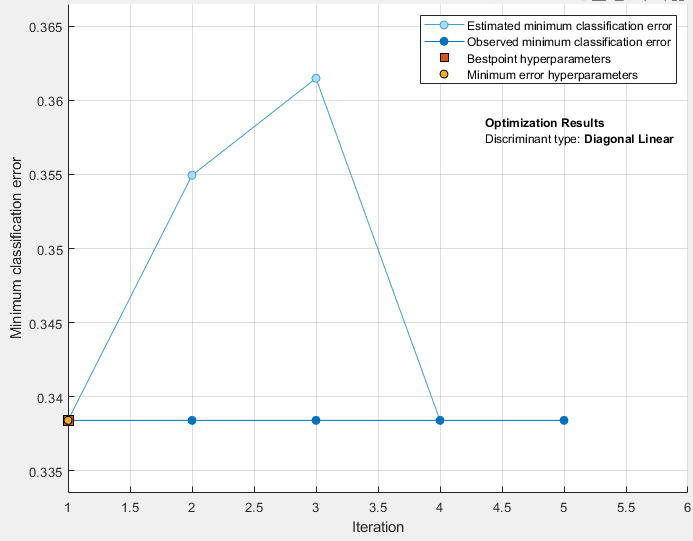

**SVM:**

Para SVM los mejores resultados se obtuvieron para gaussiano "course" por lo que este será optimizado

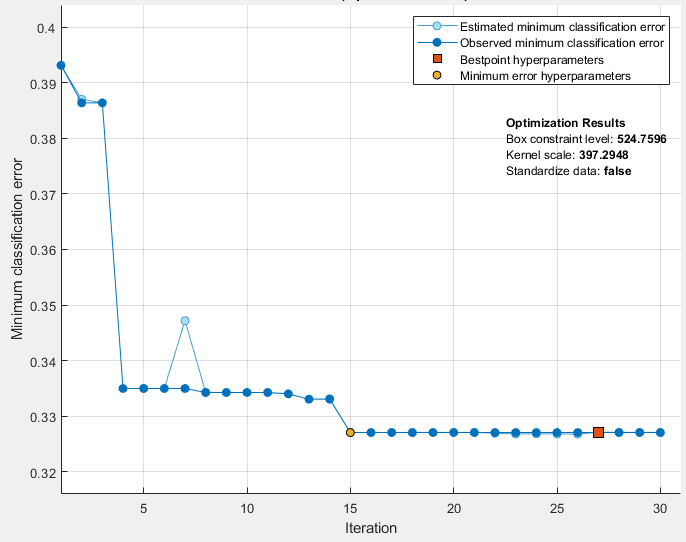

**SVM (7 características):**

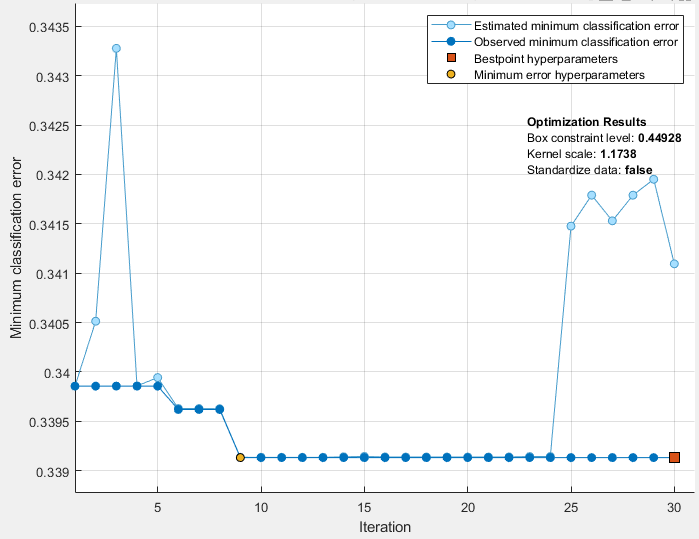

**Ensemble:**

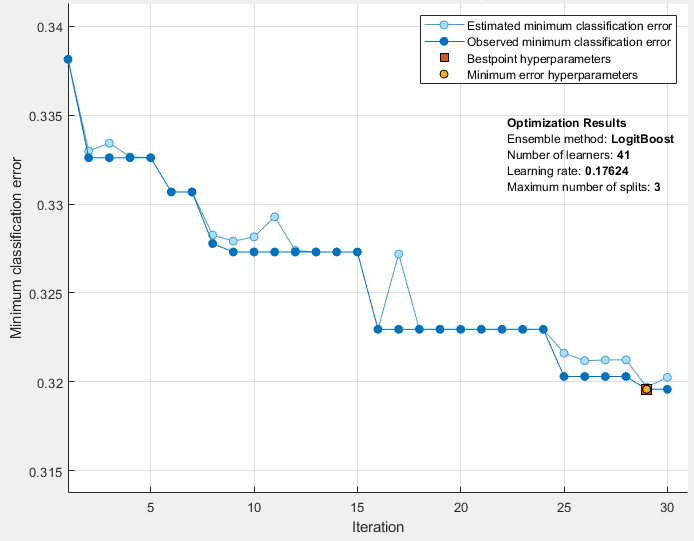

**Ensemble (7 características):**

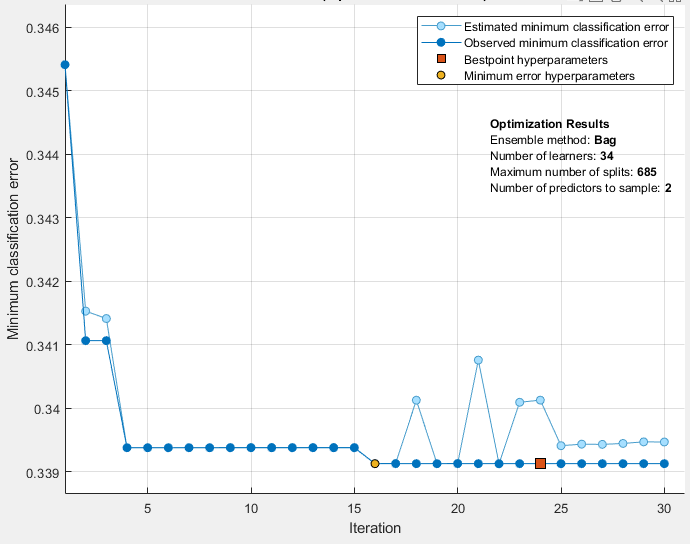

## Presentación de resultados de los modelos entrenados con el data set completo y el de características reducidas

**Arboles de decisión:**

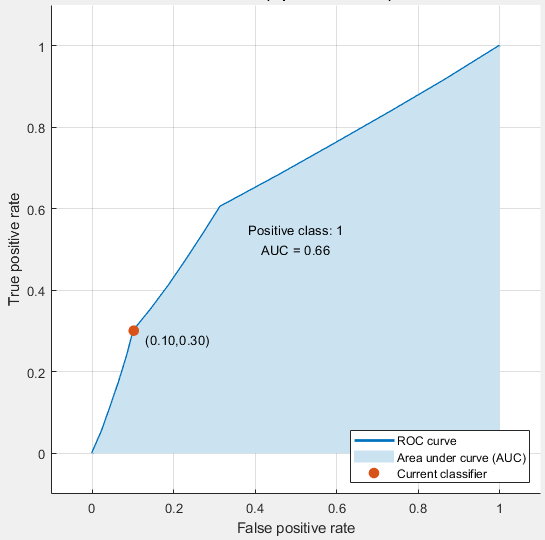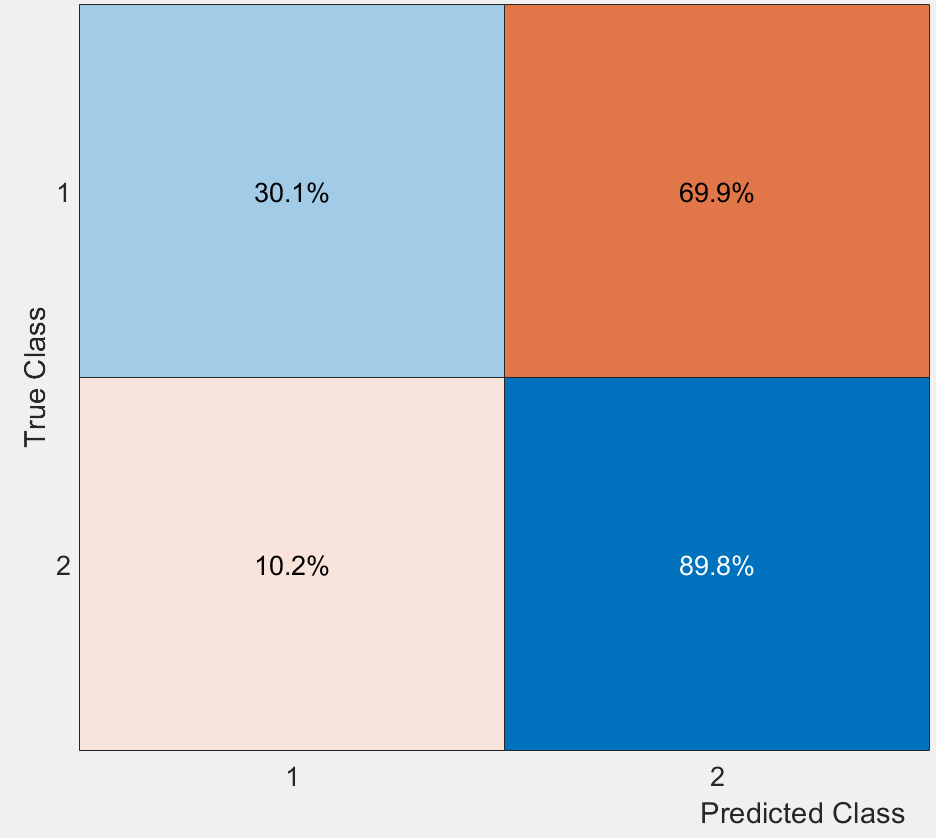

**Arboles de decisión (7 características):**

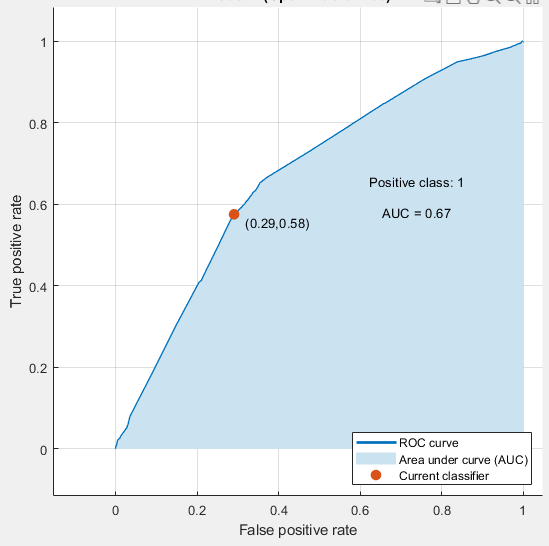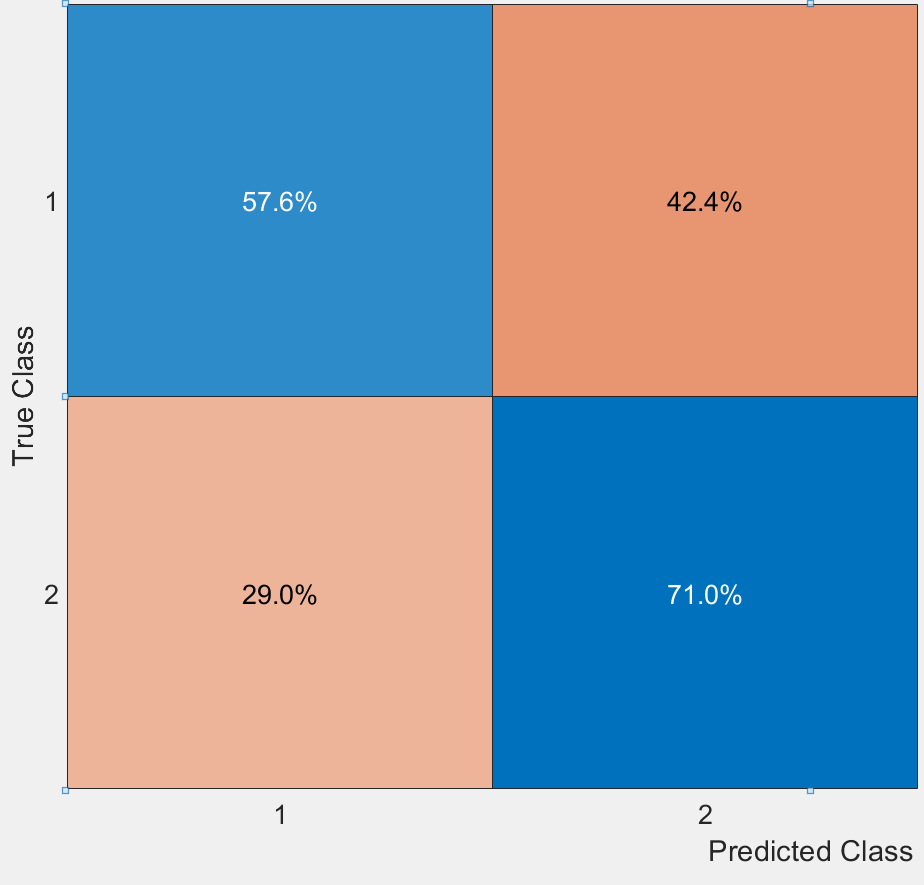

**Discriminante: **

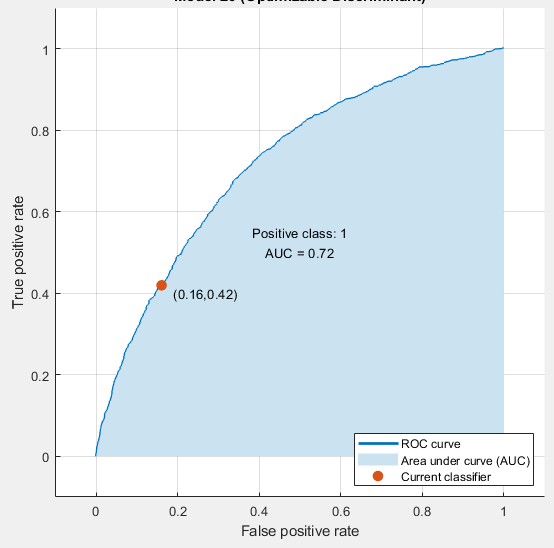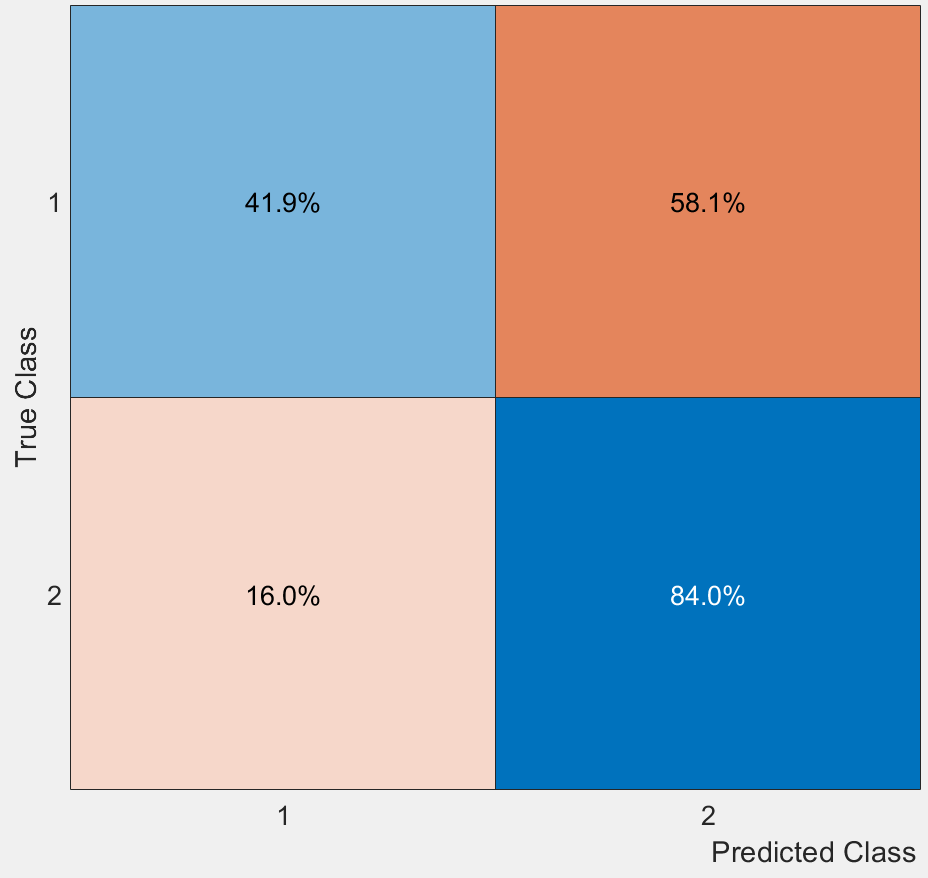

**Discriminante (7 características):**

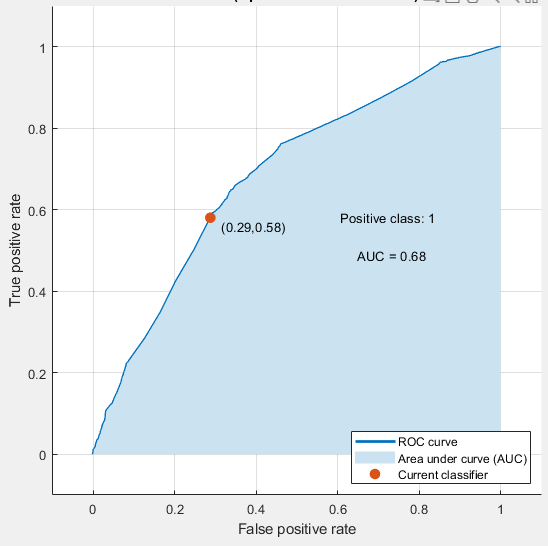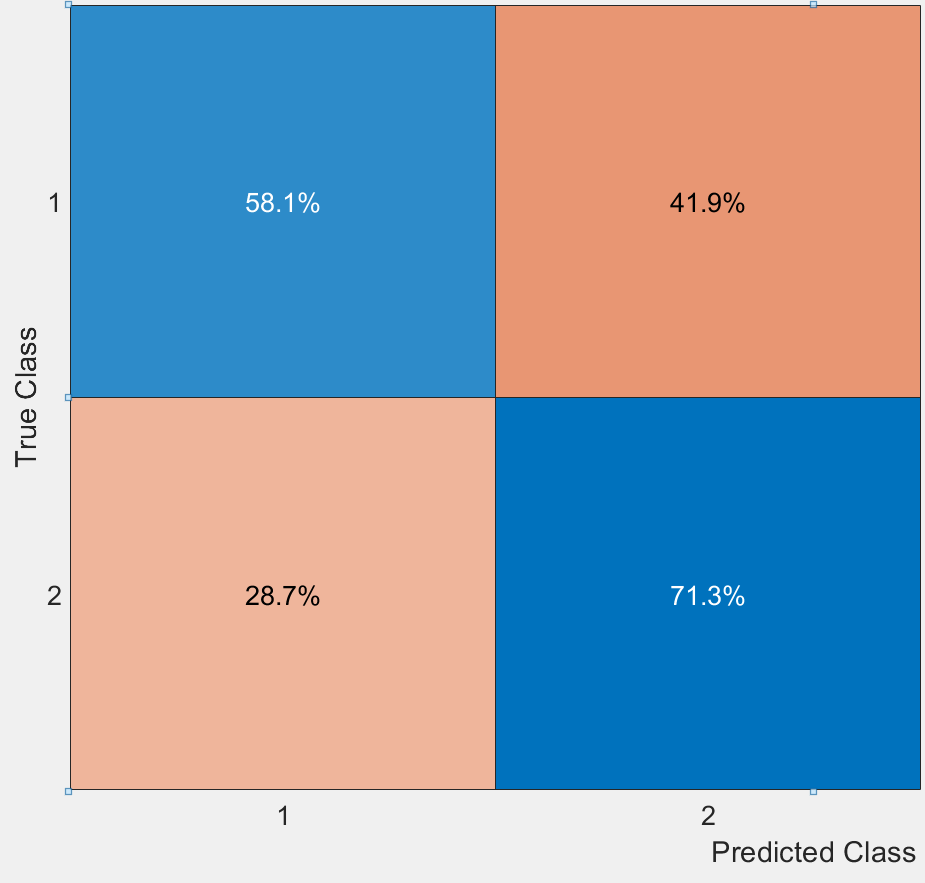

**Logistic regression:**

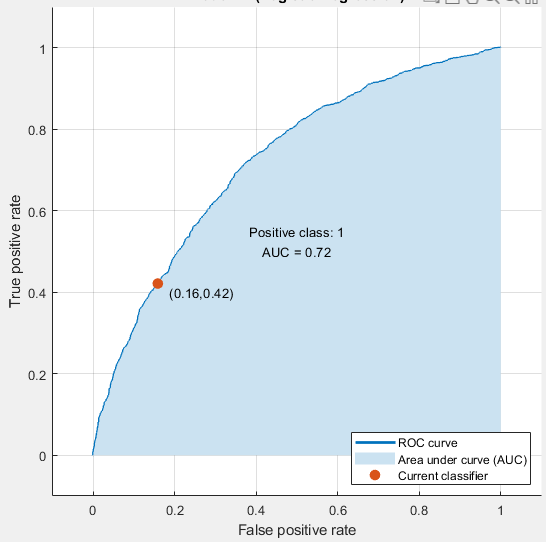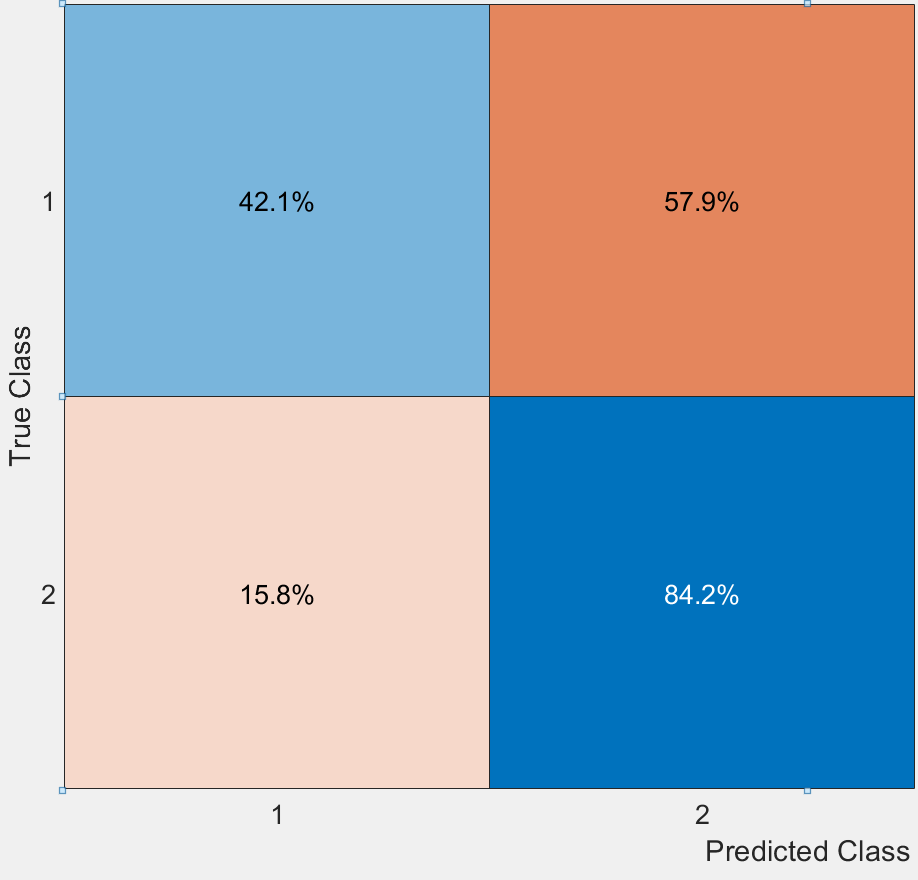

**Logistic regression (7 características):**

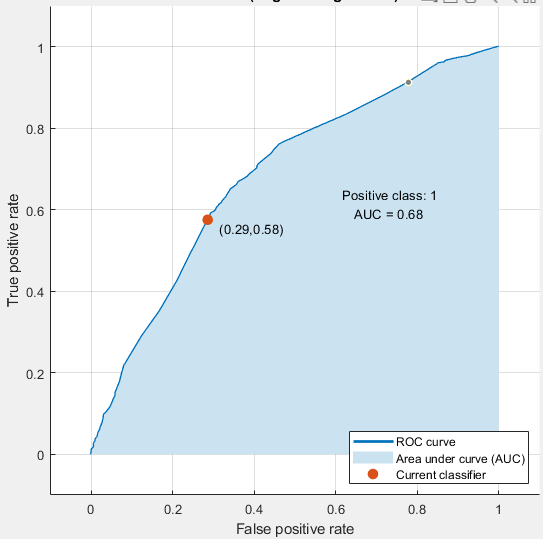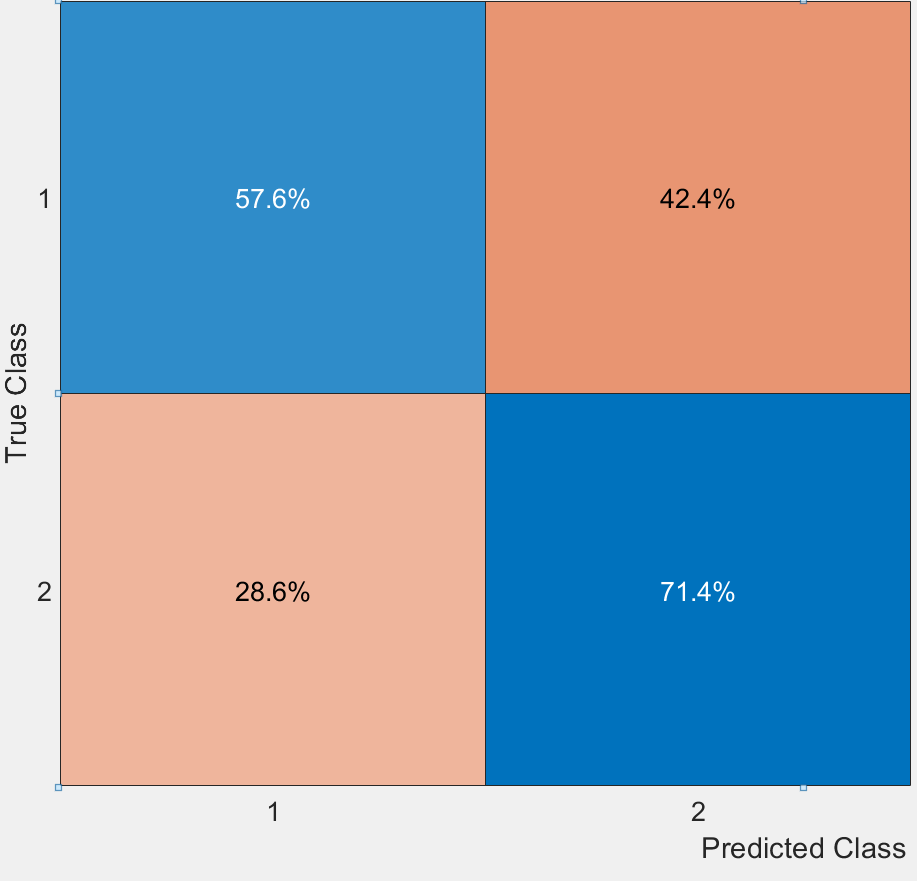

**SVM:**

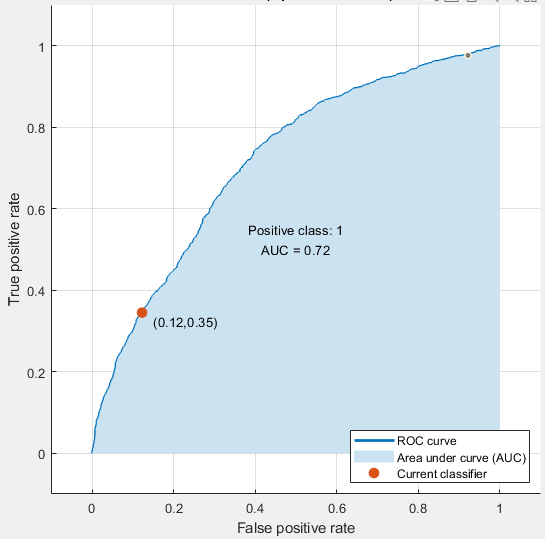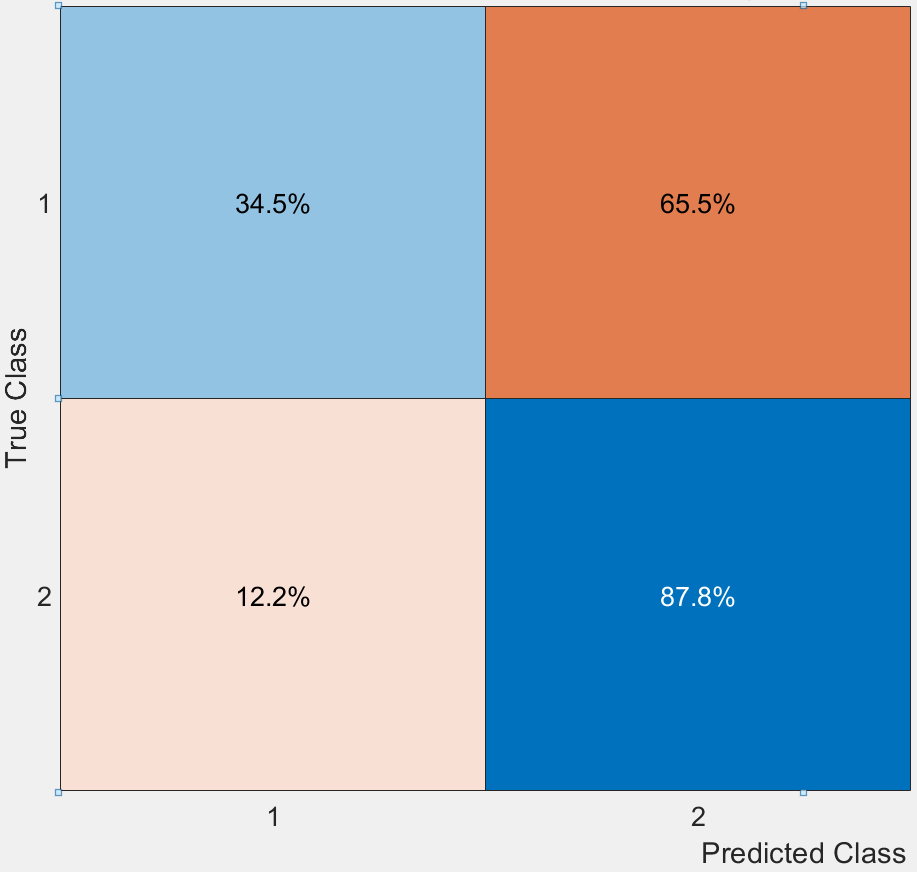

**SVM (7 características):**

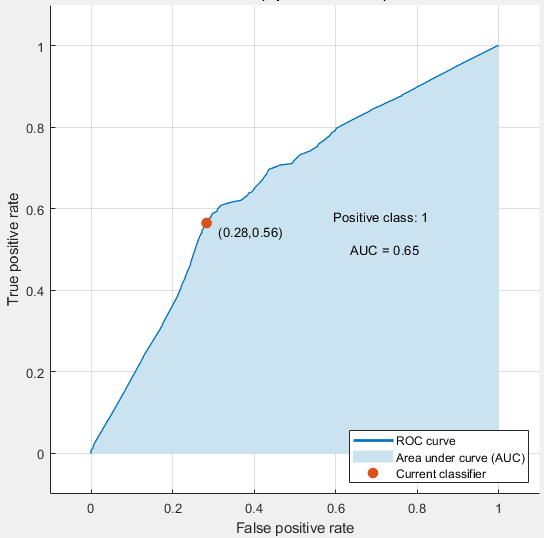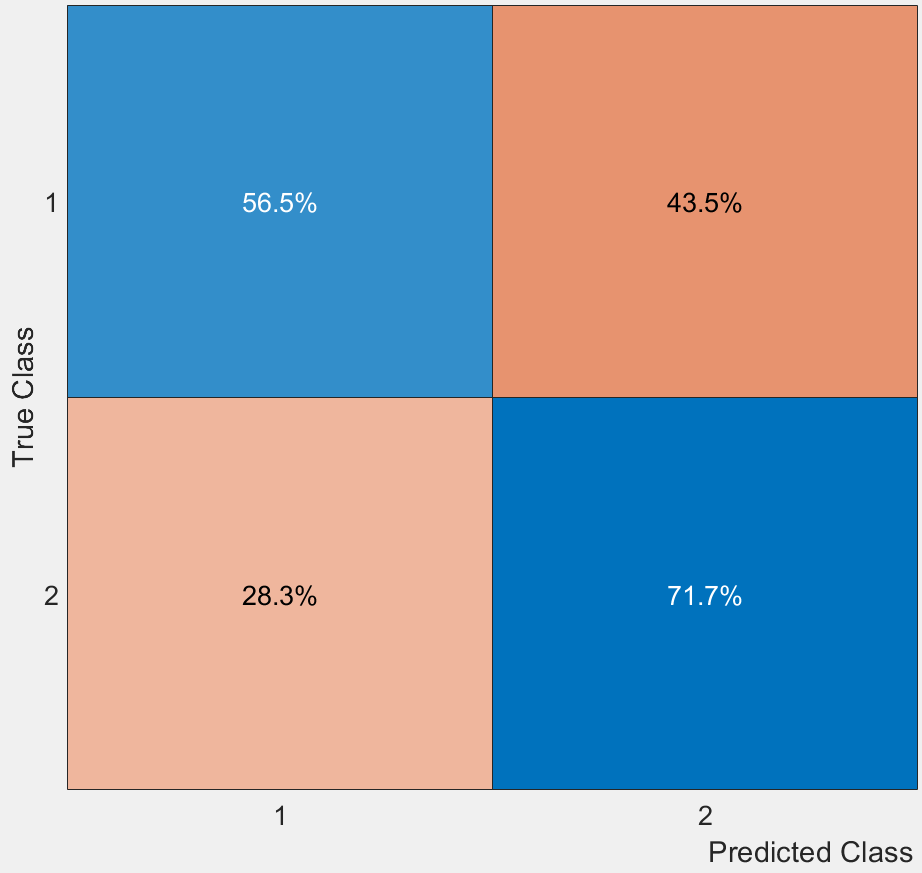

**Ensemble:**

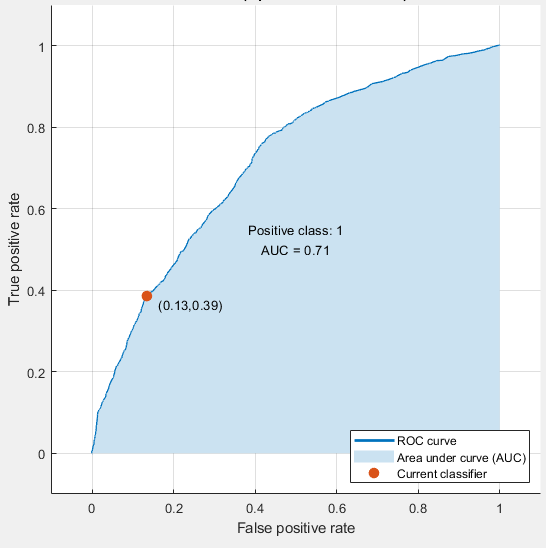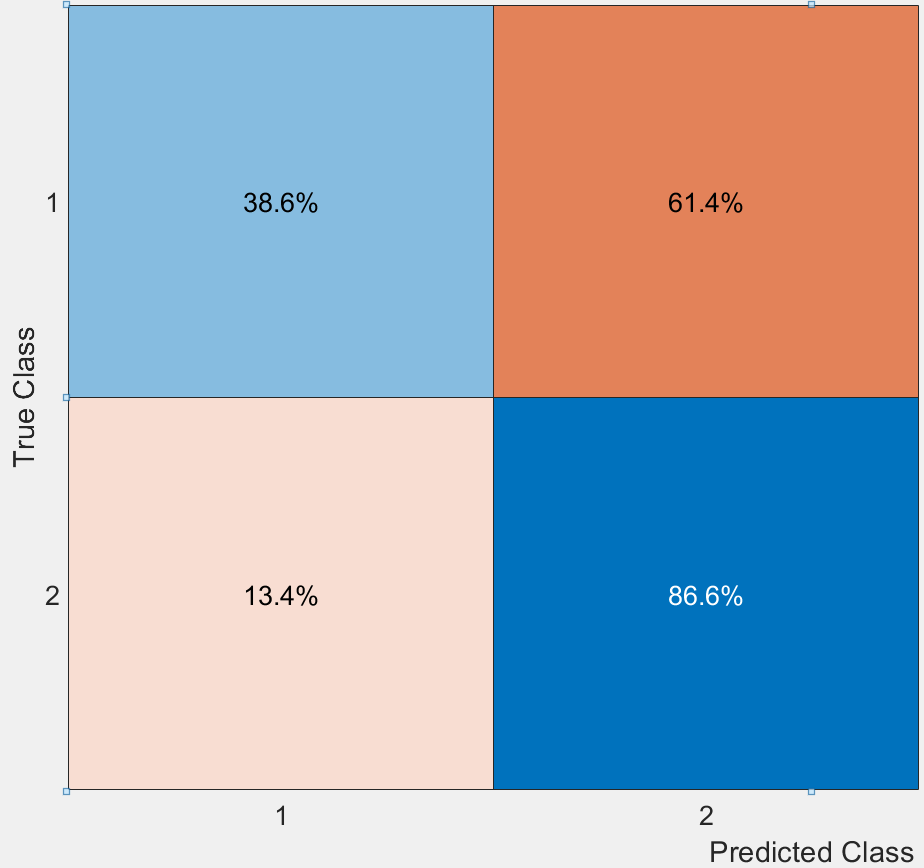

**Ensemble (7 características):**

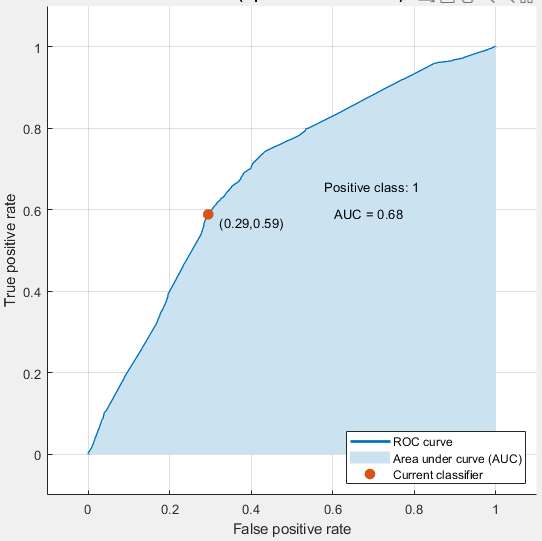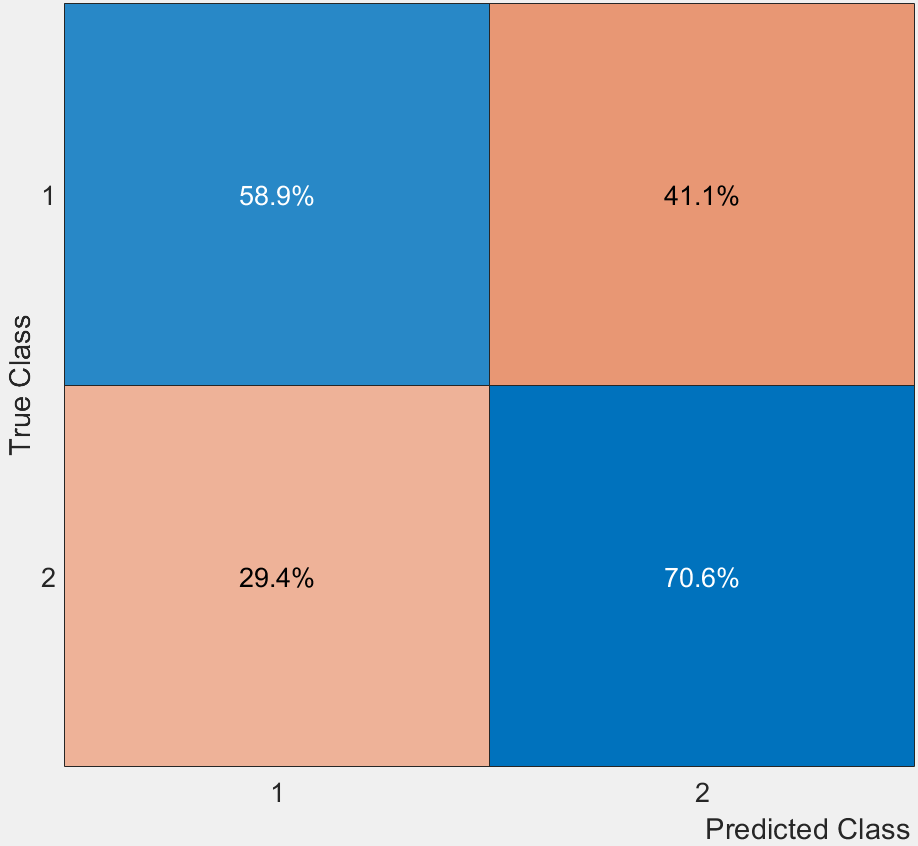

## Comparación de modelos

Para este punto se tendrán en cuenta varias cosas:

- La exactitud del modelo, mientras mayor mejor, sin llegar a un caso de sobreajuste.

- El número de parámetros en general es de interés obtener modelos que con un bajo número de parámetros sean capaces de cumplir con su objetivo a cabalidad, esto debido a que en un caso real es más difícil y costoso, en términos de dinero y tiempo obtener una cantidad grande de informaciones este caso no se les dará mayor importancia a unos parámetros sobre otros, solo será de interés el número de ellos.

- La complejidad del modelo, se preferirán modelos más simples

- Un último factor que se tendrá en cuenta para preferir un modelo sobre otro es la distribución de falsos negativos hacia cierta clase particular, i.e.  en este contexto no sería nada bueno identificar erróneamente a aquellas personas con tendencia repetitiva al intento de suicidio, mientras que identificar erróneamente a aquellos que en realidad no (falso positivo), sería más aceptable.

En cuestiones de exactitud se obtuvieron resultados que variaban entre diferentes entrenamientos de los modelos, pero en general se destacaron ensemble y Logistic Regression.

En cuanto al análisis ROC, se tiene resultados poco satisfactorios, lo que quiere decir que la distinción entre clases no es óptima. En cuanta al valor AUC los mejores pertenecen a Discriminant, Logistic Regression y SVM

Teniendo en cuenta el último factor que se mencionó para la comparación de los modelos, lo que se busca es maximizar la predicción correcta de la etiqueta 1 {si a intentos previos de suicidio}, en este sentido la mayoría de los modelos son deficientes. Pero en general los de 7 características se comportan mejor que los completos. Así, uno de los mejores sería el de discriminante linear con 7 características ya que es el que más se acerca a lo requerido, tienen poco número de características y no hace parte de los modelos demasiado complejos

% Model             AUC
% TreeFull			0,66
% Tree7				0,67
% DiscriminantFull	0,72
% Discriminant7		0,68		
% LogRegFull		0,72
% LogReg7			0,68 
% SVMFull			0,72
% SVM7				0,65
% EnsembleFull		0,71
% Ensemble7			0,68

*Las funciones para entrenar los modelos se encuentra en la carpeta "models".*

[trainedClassifierTreeFull, validationAccuracyTreeFull] = tree_full(cds_imputed);
[trainedClassifierTree7, validationAccuracyTree7] = tree_7(cds_imputed);
[trainedClassifierSVMFull, validationAccuracySVMFull] = SVM_full (cds_imputed);
[trainedClassifierSVM7, validationAccuracySVM7] = SVM_7(cds_imputed);
[trainedClassifierLogRegFull, validationAccuracyLogRegFull] = logReg_full(cds_imputed);

[trainedClassifierLogReg7, validationAccuracyLogReg7] = logReg_7(cds_imputed);
[trainedClassifierEnsembleFull, validationAccuracyEnsembleFull] = ensemble_full(cds_imputed);
[trainedClassifierEnsemble7, validationAccuracyEnsemble7] = ensemble_7(cds_imputed);
[trainedClassifierDiscriminantFull, validationAccuracyDiscriminantFull] = discriminant_full(cds_imputed);
[trainedClassifierDiscriminant7, validationAccuracyDiscriminant7] = discriminant_7(cds_imputed);

validationAccuracyTreeFull,validationAccuracyTree7,validationAccuracySVMFull,validationAccuracySVM7,validationAccuracyLogRegFull,validationAccuracyLogReg7,validationAccuracyEnsembleFull,validationAccuracyEnsemble7,validationAccuracyDiscriminantFull,validationAccuracyDiscriminant7

validationAccuracyTreeFull = 0.6674

validationAccuracyTree7 = 0.6589

validationAccuracySVMFull = 0.6720

validationAccuracySVM7 = 0.6577

validationAccuracyLogRegFull = 0.6780

validationAccuracyLogReg7 = 0.6602

validationAccuracyEnsembleFull = 0.6756

validationAccuracyEnsemble7 = 0.6522

validationAccuracyDiscriminantFull = 0.6797

validationAccuracyDiscriminant7 = 0.6623


max_accuracy = max([ ...
validationAccuracyTreeFull validationAccuracyTree7 validationAccuracySVMFull validationAccuracySVM7 ...
validationAccuracyLogRegFull validationAccuracyLogReg7 validationAccuracyEnsembleFull ...
validationAccuracyEnsemble7 validationAccuracyDiscriminantFull validationAccuracyDiscriminant7
])

max_accuracy = 0.6797


idx = find([ ...
validationAccuracyTreeFull validationAccuracyTree7 validationAccuracySVMFull validationAccuracySVM7 ...
validationAccuracyLogRegFull validationAccuracyLogReg7 validationAccuracyEnsembleFull ...
validationAccuracyEnsemble7 validationAccuracyDiscriminantFull validationAccuracyDiscriminant7
]' == max_accuracy,1)

idx = 9


aux = [{'validationAccuracyTreeFull'}
    {'validationAccuracyTree7'}
    {'validationAccuracySVMFull'}
    {'validationAccuracySVM7'}
    {'validationAccuracyLogRegFull'}
    {'validationAccuracyLogReg7'}
    {'validationAccuracyEnsembleFull'}
    {'validationAccuracyEnsemble7'}
    {'validationAccuracyDiscriminantFull'}
    {'validationAccuracyDiscriminant7'}];
best_val_accur = aux(idx)

best_val_accur = 1×1 cell array
    {'validationAccuracyDiscriminantFull'}


## Conclusiones 

Como se puede observar, los resultados no juegan a nuestro favor. Esto se ve reflejado en la precisión de los modelos y en los árboles de decisión. Dicha situación puede ser debida a la gran cantidad de datos categóricos que poseemos, ya que, junto a una carencia de información, no nos entregan los resultados adecuados. Ejemplo de esto es, una de las características que mejor información debería brindarnos es la reincidencia, pero a la hora de revisar el parámetro, no es autosuficiente esta categoría debido a algunos factores, como el estado de vida actual de los individuos (si están vivos  o muertos).

En cuanto a las características más relevantes que destacó Feature selection son bastante apropiadas, esto podría significar que se halló una mayor concurrencia o un patrón específico de estas señales en el recorrido de los datasets.

Sería de gran ayuda poder obtener un dataset con datos relacionados sobre los intentos previos de suicidio de las personas  y que la información que esta contenga sea completa, al menos lo suficiente para poder alcanzar los objetivos que se propusieron desde el principio.

También se espera, ya sea en un futuro avance o en la versión final del proyecto, incluir predicciones no solo probabilísticas sino también determinísticas, además de una comparativa  de los modelos no solo usando datos de validación sino también apartar datos para test y determinar resultados a partir de eso. 

- `Hablar de porque nuestros modelos son tan malos -Posibles razones: `*¿*`se hicieron las cosas mal?  `*¿*`Caracter`*í*`sticas comunes para aquellos que son reincidentes por lo que es dif`*í*`cil separarlos de aquellos que no? Preferiblemente una mayor cantidad de datos (y tambi`*é*`n mejor calidad ya que hab`*í*`a muchos datos faltantes)-`

- `Hay que comentar que podr`*í*`a significar seg`*ú*`n el contexto esas 7 caracter`*í*`sticas m`*á*`s importantes`

- `Como seria excelente de acuerdo con la propuesta inicial poder conseguir datasets con informaci`*ó*`n de personas que han intentado previamente el suicidio como de aquella que no`

- `En pr`*ó*`ximos avances/desarrollos incluir predicciones no solo probabil`*í*`sticas sino tambi`*é*`n determin`*í*`sticos.`

## Referencias (arreglar)

[https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html)

[https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html](https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html)

[https://www.mathworks.com/help/stats/assess-classifier-performance.html](https://www.mathworks.com/help/stats/assess-classifier-performance.html)

[https://towardsdatascience.com/intuitive-hyperparameter-optimization-grid-search-random-search-and-bayesian-search-2102dbfaf5b](https://towardsdatascience.com/intuitive-hyperparameter-optimization-grid-search-random-search-and-bayesian-search-2102dbfaf5b)

[https://towardsdatascience.com/automated-machine-learning-hyperparameter-tuning-in-python-dfda59b72f8a](https://towardsdatascience.com/automated-machine-learning-hyperparameter-tuning-in-python-dfda59b72f8a)

[https://towardsdatascience.com/workflow-of-a-machine-learning-project-ec1dba419b94](https://towardsdatascience.com/workflow-of-a-machine-learning-project-ec1dba419b94)

[https://www.mathworks.com/help/stats/feature-selection.html](https://www.mathworks.com/help/stats/feature-selection.html)

[https://towardsdatascience.com/understanding-confusion-matrix-a9ad42dcfd62](https://towardsdatascience.com/understanding-confusion-matrix-a9ad42dcfd62)

[https://towardsdatascience.com/understanding-auc-roc-curve-68b2303cc9c5](https://towardsdatascience.com/understanding-auc-roc-curve-68b2303cc9c5)

% %Test con el data set original sin preprocesar
%test = readtable('suicidio_null.csv'); size_test = size(test) 
%Extraño: con k-folds resultados de mas del 70% de exactitud
%Test con cds_imputed sin validacion: overfit extremo, 97% de exactitud

`Notas`

`Modelos sugeridos por el profesor: Regresion logistica, SVM, Arboles de decision, Redes neuronales, LMP, Random Forest`

`Intent_prev{1 = SI; 2 = NO}`

`Para traducir graficas{``Mínimo error de clasificación,Iteración,Mínimo error de clasificación observado,Hiperparámetros de error mínimo}`

`ROC: Que tan bien puede predecir entre clases`

`Sensibilidad  vs  1 - especificidad`

`AUC: da una idea de que tan bueno es el modelo`

`Invariable con respecto a escala`

`Invariable con respecto a umbral de clasificacion`

`Exactitud (acuraccy): relacionTP y TN vs total`

`Sensibilidad(recall): proporcion de TP / P`

`Especifidad:  proporcion de TN / N`